clc
clear

h = 0.1; n = 1/h;
yPredicted = zeros(1,n+1);
yPredicted(1) = -1; yCorrected(1) = -1; x(1) = 0;
yDerivative = zeros(1,n);

syms X Y;
myFunction = -2*X-Y;
x = 0:h:1;
yTheoretical = -3.*exp(-x)-2.*x+2;

for i=1:n
    yDerivative(i) = subs(myFunction, [X,Y], [x(i),yPredicted(i)]);
    yPredicted(i+1) = yPredicted(i) + h*yDerivative(i);
    if(i==n)
        yDerivative(i+1) = -2*x(i)-yPredicted(i);
    end
end

for i=1:n
    yCorrected(i+1) = yPredicted(i) + h*(yDerivative(i)+yDerivative(i+1))/2;
end

error = yTheoretical(end) - yCorrected(end)

error = -0.0576

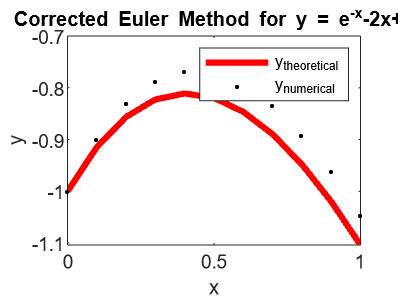

errorPercentage = error./yTheoretical;

plot(x,yTheoretical,'LineWidth',3,'Color','r'), hold on,
plot(x,yPredicted,'.k')
title("Corrected Euler Method for y = e^{-x}-2x+2")
xlabel("x"), ylabel("y")
legend("y_{theoretical}","y_{numerical}")